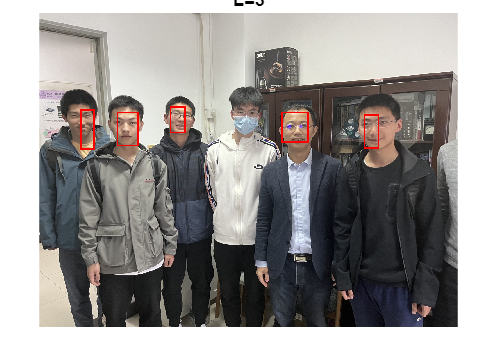

clear
clc

testImg = imread('TestImages\3','bmp');

figure
frames = FaceDetection(testImg,3,0);
rslt3 = FrameAdder(testImg,frames,5);
imshow(rslt3);
title('L=3');

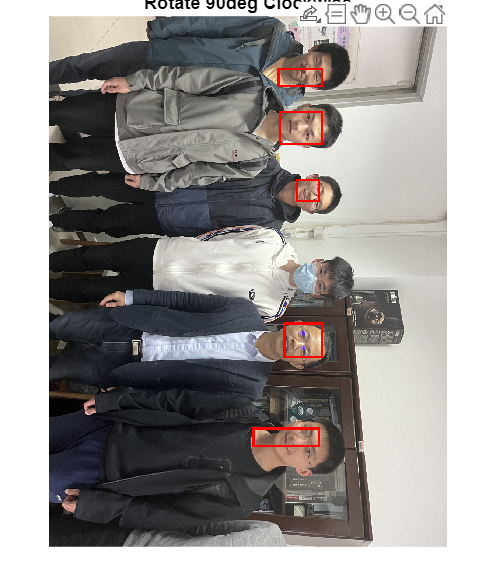


figure
img90=imrotate(testImg,-90);
frames = FaceDetection(img90,3,0);
rslt90 = FrameAdder(img90,frames,5);
imshow(rslt90);
title('Rotate 90deg Clockwise');

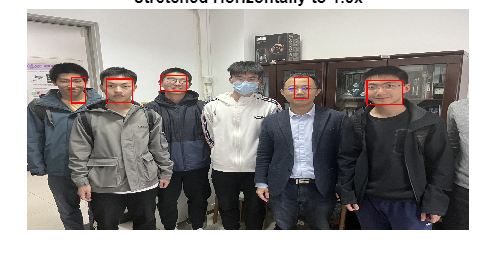


figure
[h, w] = size(testImg,[1 2]);
img_wide=imresize(testImg,[h ceil(1.5*w)]);
frames = FaceDetection(img_wide,3,0);
rslt_wide = FrameAdder(img_wide,frames,5);
imshow(rslt_wide);
title('Stretched Horizontally to 1.5x');

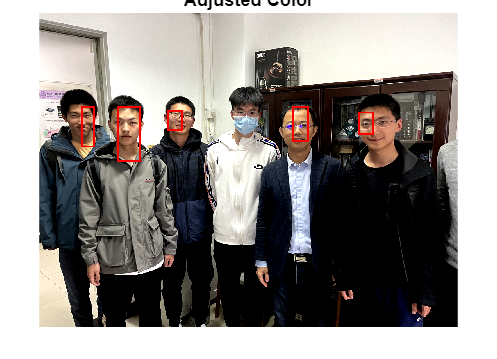


figure
img_adj = imadjust(testImg,[0.2,0.2,0.2;0.9,0.9,0.9]);
frames = FaceDetection(img_adj,3,0);
rslt_adj = FrameAdder(img_adj,frames,5);
imshow(rslt_adj);
title('Adjusted Color');